f = @(x) 1/sqrt(2.*pi) * exp((-1/2)*x.^2)

f = function_handle with value:
    @(x)1/sqrt(2.*pi)*exp((-1/2)*x.^2)


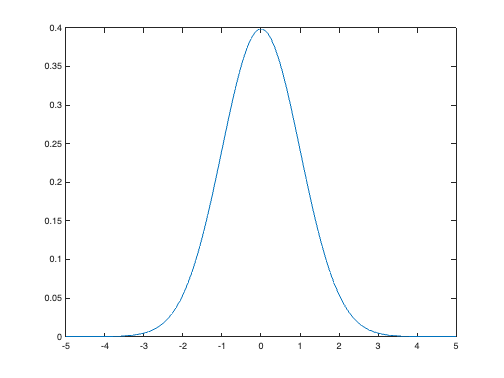

x = linspace(-5, 5, 100);
plot(x, f(x))

Then pick a dx to split up the rectangles in the pdf

then between [t_a, t_b] to map between

t_a = -10

t_a = -10

t_b = 10

t_b = 10

Next up compute the area of each rectangle

 num_rectangles = 100

num_rectangles = 100

 dx = (t_b - t_a) / num_rectangles

dx = 0.2000

 areas = zeros(1, num_rectangles);
 for i=1:num_rectangles
     x_i = t_a + (i-1)*dx;
     width = dx; % dx is rectangle width
     height = f(x_i); % rectangle height
     areas(i) = width*height;
 end
 sum(areas) % close to 1

ans = 1

Then you ought to be able to sample from the random uniform function and find which rectangle we fall into

function idx = find_bin(r, uniform_bins)
    idx = length(uniform_bins);
    for i=1:length(uniform_bins)
        if r < uniform_bins(i)
            idx = i;
            break;
        end
    end
end

uniform_bins = cumsum(areas);
rng(0)
r = rand(1, 1000)

r =     0.8147    0.9058    0.1270    0.9134    0.6324    0.0975    0.2785    0.5469    0.9575    0.9649    0.1576    0.9706    0.9572    0.4854    0.8003    0.1419    0.4218    0.9157    0.7922    0.9595    0.6557    0.0357    0.8491    0.9340    0.6787    0.7577    0.7431    0.3922    0.6555    0.1712    0.7060    0.0318    0.2769    0.0462    0.0971    0.8235    0.6948    0.3171    0.9502    0.0344    0.4387    0.3816    0.7655    0.7952    0.1869    0.4898    0.4456    0.6463    0.7094    0.7547


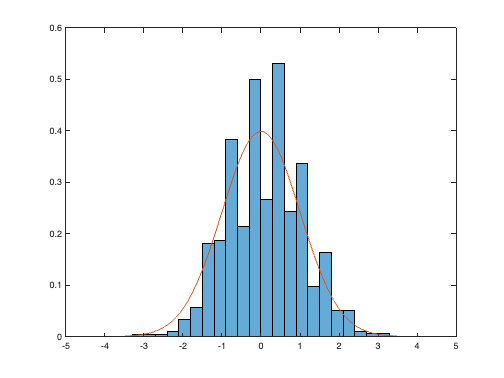

transformed = zeros(1, length(r));
for i=1:length(r)
    idx = find_bin(r(i), uniform_bins);
    mapped_x_i = t_a + (idx-1)*dx;
    transformed(i) = mapped_x_i + dx/2; % take middle of bin instead of start
end

histogram(transformed, "Normalization", "pdf")
hold on
plot(x, f(x))
hold off

Is there a vectorized way to do this?

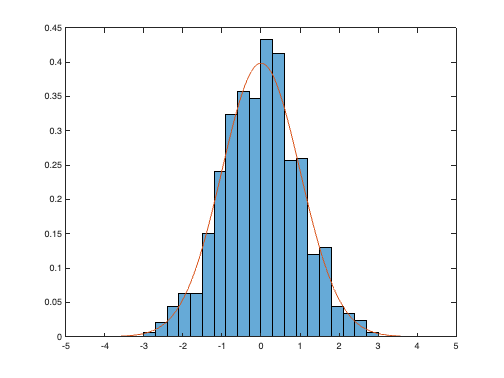

function transformed = rand_to_pdf(rand_sample, pdf, t_a, t_b, num_rectangles)
    % compute target mapping areas and what x they correspond to
    dx = (t_b - t_a) / num_rectangles;
    target_xs = t_a:dx:(t_b-dx); % rectangle start coordinate x_i
    target_ys = pdf(target_xs); % pdf(x_i) or rectangle height
    areas = dx .* target_ys;  % rectangle widths times heights
    
    % then map the random uniform to those xs from the pdf
    % weighed by the pdf area for that rectangle
    r = rand_sample(:);
    source_bins = cumsum(areas); % the bins in the uniform distrubtion sized by the pdf areas
    target_rectangles_indexes = arrayfun(@(r_i) find_bin(r_i, source_bins), r); % map the rand uniform to a rectangle in the pdf
    transformed = reshape(target_xs(target_rectangles_indexes), size(rand_sample)); % grab the pdf x_i coordinate from the rectangles
end

sample = rand_to_pdf(rand_eca(1000, 1), f, -3, 3, 100);
histogram(sample, "Normalization", "pdf")
hold on
plot(x, f(x))
hold off

function idx = find_thread_over_rows(condition)
    %  https://www.mathworks.com/help/matlab/ref/max.html
    [~, idx] = max(condition, [], 2);
end
rs = reshape(rand(1, 100), [], 1); % column vector
find_thread_over_rows(rs < cumsum([0.1, 0.2, 0.7]))

ans =      3
     3
     1
     3
     3
     3
     3
     2
     3
     3
